# **模拟数据**

**模拟数据**

clear
theta = 70.5;
n = 1.5;
lambda = 680;
kapa = 8;
phi = 0.1*pi;
scale_factor = 0.1;
M_size = 501;
theta_spp = 0;
theta_res = 70.5;
[Ei,Es,F,I] = wave_generate(lambda,n,kapa,theta,phi,scale_factor,M_size,theta_spp,theta_res);

**解卷积**

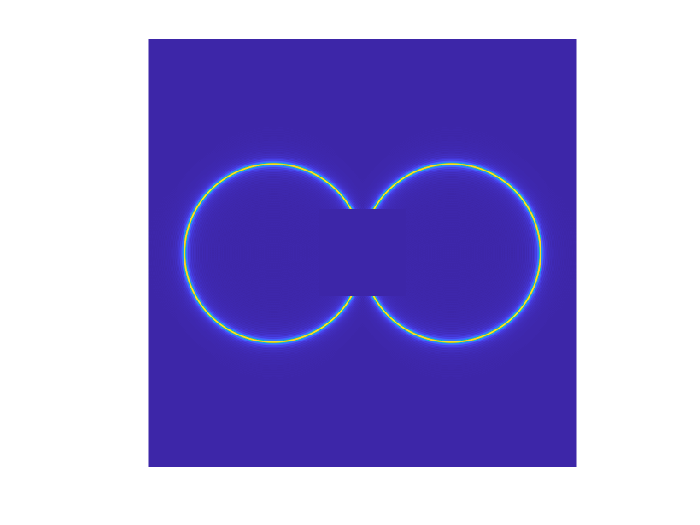


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


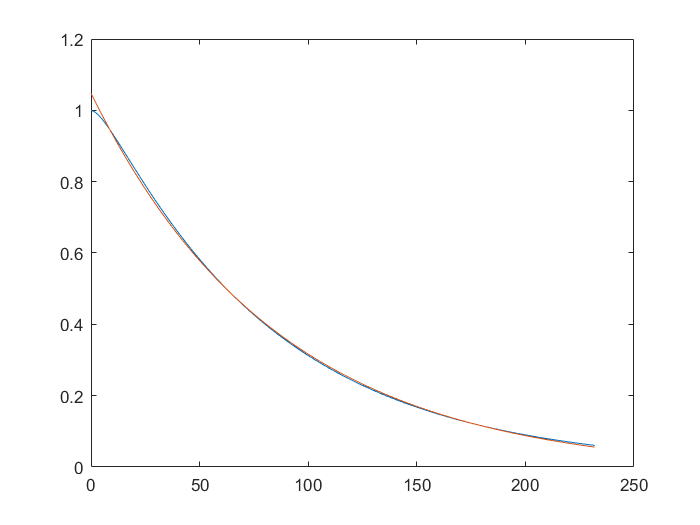

obj = Yu(I);
obj = obj.k_gamma(5,0.1,0);

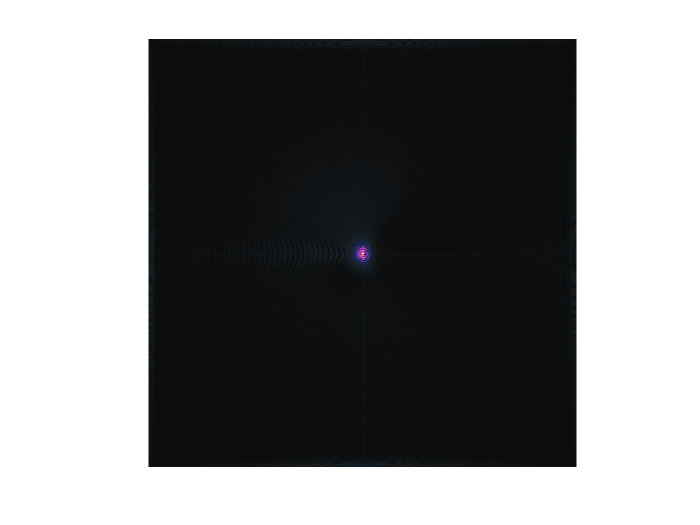

obj = obj.ForMatrixes(80,20,10,'l');     % 要点：ks2尽量小以便快速截断
figure
imagesc(obj.Rcn)
axis off
axis equal
colormap(sunglow)

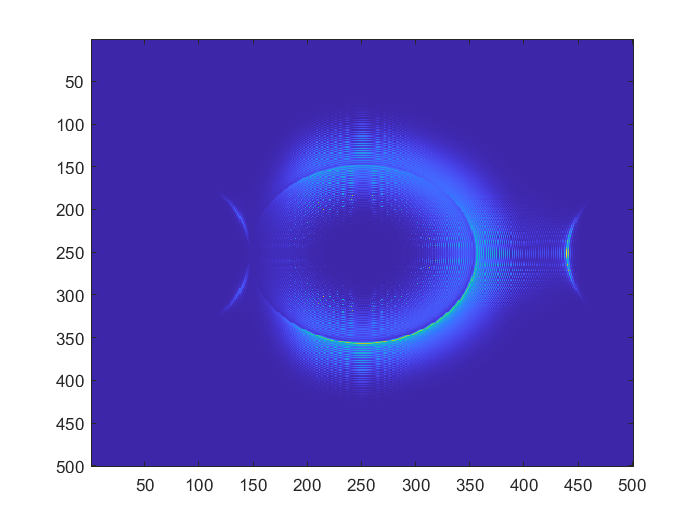

figure
imagesc(abs(obj.FO))

**我的方法**

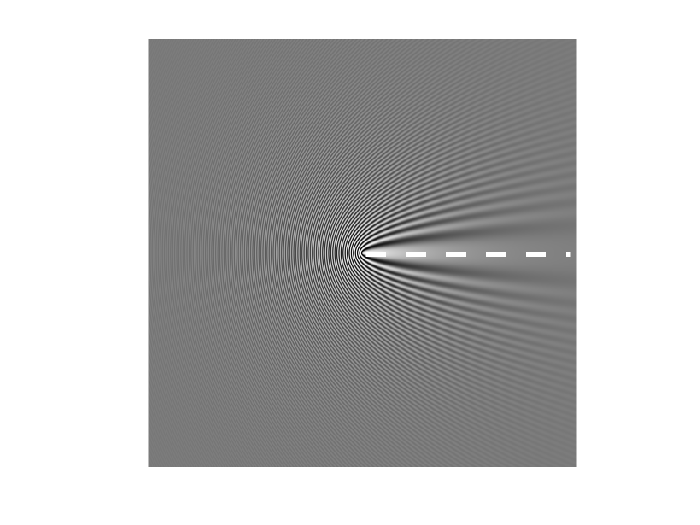

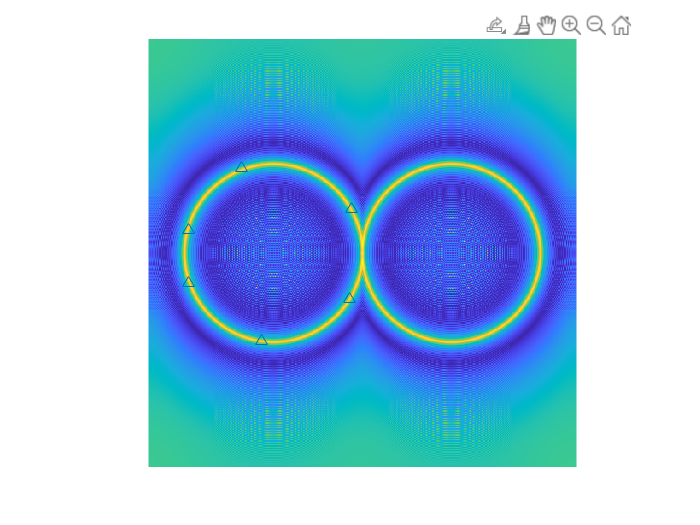

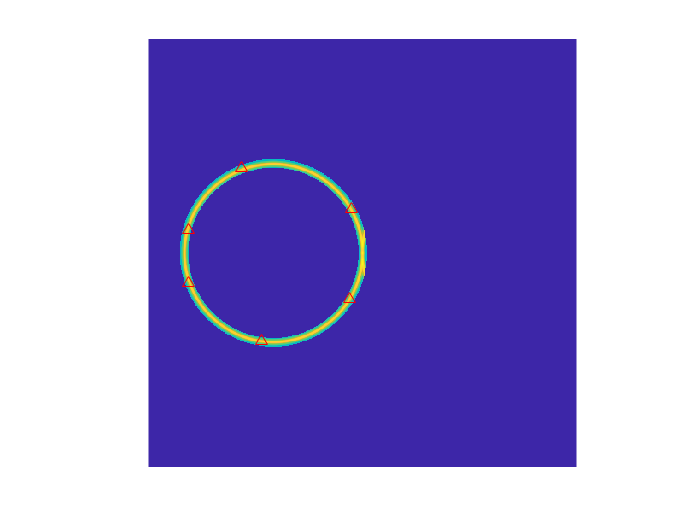

[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,0);

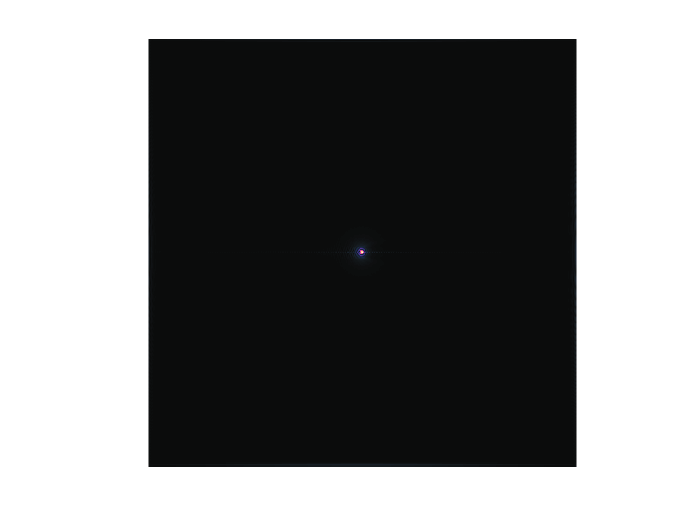

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.25,'G',2,'in');
I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(sunglow)

**绘图**

row = (1:51) + 225;col = row;
YuFig = abs(obj.Rcn(row,col));
figure
imagesc(YuFig);axis off;axis equal;colormap(sunglow)
line([7,17],[44,44],'linewidth',8,'color','w')
WanFig = abs(I_rcn(row,col));
figure
imagesc(WanFig);axis off;axis equal;colormap(sunglow)
line([7,17],[44,44],'linewidth',8,'color','w')

# **纳米颗粒**

**导入数据**

close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220408_PsNPs_colission\PsNPs_300nm\BG';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);

I = double(imread(fullfile(tiffpath,tiffs(1).name))) - BG;
F = fftshift(fft2(fftshift(I)));
figure
imagesc(I)
axis off
axis equal
colormap(sunglow)

**解卷积**

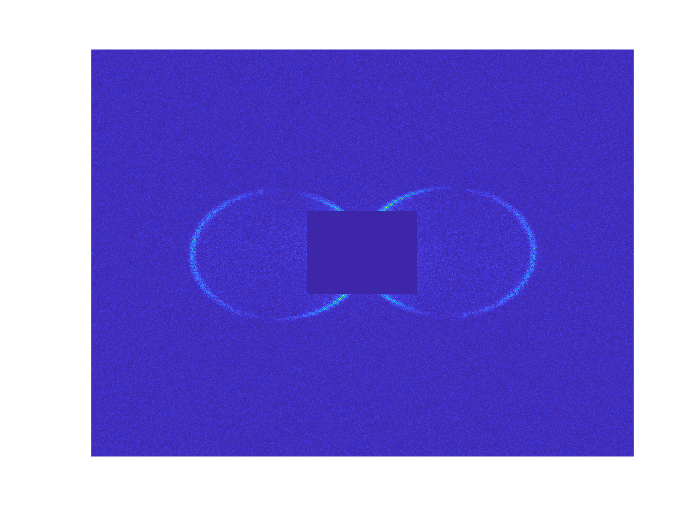

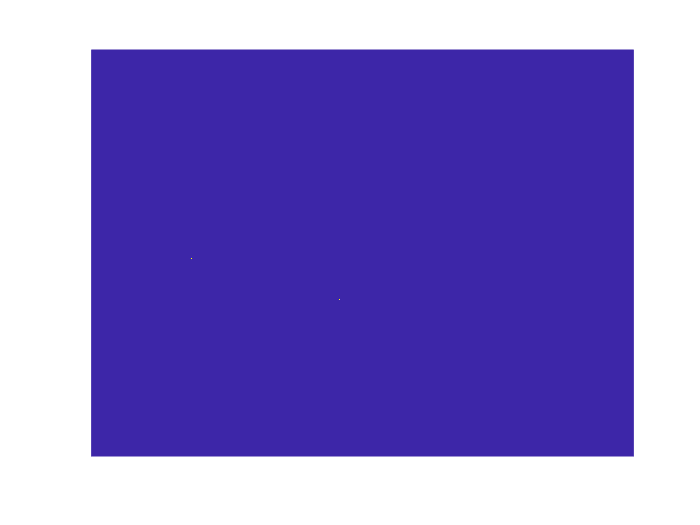

索引超出数组元素的数目(0)。

出错 findcircle (第 29 行)
            level=answer(1);

出错 Yu/k_gamma (第 27 行)
            [center_raw,center_col,R_,~] = findcircle(F_,thickness,fct,method);

obj = Yu(I);
obj = obj.k_gamma(5,0.1,1);

% obj = obj.ForMatrixes(90,15,5,'l');     % 保持高分辨但留有尾巴
obj = obj.ForMatrixes(80,30,10,'l');      % 消除尾巴但分辨率下降
figure
imagesc(obj.Rcn)
axis off
axis equal
colormap(sunglow)
figure
imagesc((abs(obj.FO)))

**我的方法**

[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);
peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.25,'G',2);
I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(sunglow)

**绘图**

col = 572:622;row = 395:445;
saveroute = 'D:\工作汇总\文章\散射场重构\秦火之遗\修改\Figs\Yu';
YuFig = abs(obj.Rcn(row,col));
figure
imagesc(YuFig);axis off;axis equal;colormap(sunglow)
line([7,7+1000/74],[44,44],'linewidth',8,'color','w')
WanFig = abs(I_rcn(row,col));
figure
imagesc(WanFig);axis off;axis equal;colormap(sunglow)
line([7,7+1000/74],[44,44],'linewidth',8,'color','w')
IFig = I(row,col);
figure
imagesc(IFig);axis off;axis equal;colormap(sunglow)
line([7,7+1000/74],[44,44],'linewidth',8,'color','w')


**剖面图**

[int_Wan,x,y] = LineCut(WanFig);
int_Wan = int_Wan/max(int_Wan);
int_I = LineCut(IFig,x,y);
int_I = int_I/max(int_I);
int_Yu = LineCut(YuFig,x,y);
int_Yu = int_Yu/max(int_Yu);

hl = findobj(gca,'type','line');
hl(3).XData = 1:length(int_I);
hl(3).YData = int_I + 1.3;
hl(2).XData = 1:length(int_Wan);
hl(2).YData = int_Wan;
hl(1).XData = 1:length(int_Yu);
hl(1).YData = int_Yu - 1.3;
xlim([1 49]);ylim([-1.8 4.5])

line([1,49],[1.5,1.5],'linewidth',2,'linestyle','--','color','k')
line([1,49],[0.1,0.1],'linewidth',2,'linestyle','--','color','k')
line([1,49],[-1.2,-1.2],'linewidth',2,'linestyle','--','color','k')

**保存图片**

saveas(gcf,fullfile(saveroute,'PSNP_剖面图.fig'));

# **纳米线**

**导入数据**

clear
filepath = 'D:\work\散射场\实验数据\20220315_60nmAuNPs_AgNWs\20220315_AgNWs_25fps\A1';
tiffs = dir(fullfile(filepath,'*.*tif*'));
BG = double(imread(fullfile(filepath,tiffs(43).name)));
I = double(imread(fullfile(filepath,tiffs(42).name))) - BG;
figure
imagesc(I)
F = fftshift(fft2(fftshift(I)));

**解卷积**

obj = Yu(I);
obj = obj.k_gamma(5,0.1,0);
% obj = obj.ForMatrixes(90,15,5,'l');     % 保持高分辨但留有尾巴
obj = obj.ForMatrixes(75,30,15,'l');    % 消除尾巴但分辨率下降
figure
imagesc(obj.Rcn)
axis off
axis equal
colormap(sunglow)
figure
imagesc(abs(obj.FO))

**我的方法**

[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,0);
peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.25,'G',2);
I_rcn = abs(fftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(I_rcn)
axis off
axis equal
colormap(sunglow)

**绘图**

col = 358:458;row = 190:290;
saveroute = 'D:\工作汇总\文章\散射场重构\秦火之遗\修改\Figs\Yu';
YuFig = abs(obj.Rcn(row,col));
figure
imagesc(YuFig);axis off;axis equal;colormap(sunglow)
line([15,15+1000/74],[85,85],'linewidth',8,'color','w')
WanFig = abs(I_rcn(row,col));
figure
imagesc(WanFig);axis off;axis equal;colormap(sunglow)
line([15,15+1000/74],[85,85],'linewidth',8,'color','w')
IFig = I(row,col);
figure
imagesc(IFig);axis off;axis equal;colormap(sunglow)
line([15,15+1000/74],[85,85],'linewidth',8,'color','w')


**剖面图**

x = [3.57 91.35];y = [65.75 37.20];
int_Wan = LineCut(WanFig,x,y);
int_Wan = int_Wan/max(int_Wan);
int_I = LineCut(IFig,x,y);
int_I = int_I/min(int_I);
int_Yu = LineCut(YuFig,x,y);
int_Yu = int_Yu/max(int_Yu);

hl = findobj(gca,'type','line');
hl(6).XData = 1:length(int_I);
hl(6).YData = int_I + 2.3;
hl(5).XData = 1:length(int_Wan);
hl(5).YData = int_Wan;
hl(4).XData = 1:length(int_Yu);
hl(4).YData = int_Yu - 1.3;
xlim([1 87]);ylim([-2 6])

line([1,87],[2,2],'linewidth',2,'linestyle','--','color','k')
line([1,87],[0.1,0.1],'linewidth',2,'linestyle','--','color','k')
line([1,87],[-1.2,-1.2],'linewidth',2,'linestyle','--','color','k')

**保存图片**

saveas(gcf,fullfile(saveroute,'AgNW_剖面.fig'));